# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Prerequisites

### Software Prerequisites

#### SNAP ESA

SNAP is a tool developed by the European Space Agency (ESA) to process SAR data obtained from Sentinel Satellites. SNAP is used to pre-process data in this pipeline and is essential to install.

To install SNAP please do the following:

- Download SNAP [here](https://step.esa.int/main/download/snap-download/) for your OS distribution

- Choose only the Sentinel Toolboxes installer

- Install SNAP and follow the onscreen instructions. It is only necessary to install the Sentinel-1 Toolbox

### MATLAB Prerequisites

#### M_Map

M_Map is a mapping package for MATLAB which allows data plots on different world maps.

To use M_Map please do the following:

- Download the zipped package [here](https://www.eoas.ubc.ca/~rich/map.html#download) and

- Add the extracted folder to your MATLAB path

*Note:* A copy of the M_Map package is included on the [git repo here](https://github.com/JNSRYA006/sar-parameter-extraction-pipeline/tree/main/toolboxes/m_map).

#### Wgrib_2

For Windows installation:

- Download the windows version from this website: [https://www.ftp.cpc.ncep.noaa.gov/wd51we/wgrib2/](https://www.ftp.cpc.ncep.noaa.gov/wd51we/wgrib2/)

- Make sure that you know where your *wgrib2.exe* file is as you will need that later in the script

For MacOS installation:  

- You will need to install wgrib2 natively by following the instructions on this website: [https://theweatherguy.net/blog/how-to-install-and-compile-wgrib2-on-mac-os-apple-silicon-m1-m3-clean-install-version/](https://theweatherguy.net/blog/how-to-install-and-compile-wgrib2-on-mac-os-apple-silicon-m1-m3-clean-install-version/) 

## Obtain SAR Data

SAR data from Sentinel-1A can be downloaded from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home). In order to download data, you need to register an account on the site.

Once you have registered your account, you can search for SAR data on the site by choosing the appropriate filters and region. The region you search is set by right-clicking and drawing a rectangle, otherwise you can left-click and draw the vertices of any polygon. Recomended filters are:

- **Sensing Period: **As desired

- **Satellite Platform:** S1A

- **Product Type:** GRD

- **Polarisation:** As desired

After searching with your filters, you will see all the available data within this region. Clicking on a red footprint on the map, shows a preview of these data, and the data can be downloaded from the pop-up. 

*Note: *These data are in excess of 1GB, so large amounts of storage space is required. Use an external hard drive if possible.

## **Pre-Process SAR Data**

After downloading SAR data from [Copernicus SciHub](https://scihub.copernicus.eu/dhus/#/home), open SNAP and import the data. These data can be viewed as follows:

- Click the '+' next to the dataset

- Click the '+' next to the *Bands* folder

- Open the desired band to preview the image

### Thermal Noise Calibration

**This needs to be done first**

To remove thermal noise, click *Radar -> Radiometric -> S1 Thermal Noise Removal. *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that *Remove Thermal Noise* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin removing thermal noise from the selected data and once complete will open in the *Product Explorer *sidebar.

### Radiometric Calibration

To radiometrically calibrate the SAR data, ensure that the **noise calibrated product is selected**, then click *Radar -> Radiometric -> Calibrate *This will bring up a window where the following needs to be done.

- Ensure the file will save as *BEAM-DIMAP*

- Check that **only** *Output sigma0 band* is checked in the *Processing Parameters* window

- Select a specific polarisation (If desired)

- Rename the output file (*Target Product) *if desired

- Check the *Open in SNAP* checkbox

After clicking *Run,* SNAP will begin radiometric calibration from the selected data and once complete will open in the *Product Explorer *sidebar.

### Export Incidence Angle

In order to access the incidence angle of each pixel in the SAR data, the following process needs to be followed.

- Click the '+' next to the *Tie-Point Grids* folder

- Right-click on the *incident_angle* band

- Select *Band Maths*

- Rename the band to "Incidence_Angle" and click OK

### Export Latitude and Longitude

In order to access the latitude and longitude of each pixel in the SAR data, the following process needs to be followed.

- Click the '+' next to the *Tie-Point Grids* folder

- Right-click on the *longitude* band

- Select *Band Maths*

- Rename the band to "Lon", unclick *Create Virtual Band* and click OK

- Right-click on thr *latitude* band

- Select *Band Maths*

- Rename the band to "Lat", unclick *Create Virtual Band* and click OK

### Exporting as NetCDF

In order to export these pre-processed SAR data in a format supported by MATLAB, the following process needs to be followed.

- Click *File*

- Hover over the *Export* option, and select **NetCDF4-BEAM**

- If your file explorer is opened, click on *Subset... *on the right hand side of the dialog box

- This will bring up a new window with four different menus.

- You can take a Spatial Subset of the image using either pixel or geographical coordinates in the *Spatial Subset *menu

- Ensure that under the *Band Subset* menu, your desired bands are selected, as well as your created ***Incidence_Angle, Lat and Lon***** bands. **

- Ensure that under the *Metadata Subset* menu, all options are selected

- After checking all of these parameters, click OK, and name the file as desired and save it in your desired location

## Take transects and subdivide

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/S1A_IW_GRDH_1SDV_20231020_tnr_Cal.nc";
% Import data values
ncImport = ncinfo(filepath);
% Update the band to import as required
sarData = ncread(filepath,'Sigma0_VV')';
metadata = ncinfo(filepath,'metadata');
incidenceAngleFull = ncread(filepath,'Incidence_Angle')';
latGrid = ncread(filepath,'Lat')';
lonGrid = ncread(filepath,'Lon')';

## View SAR Data

Choose whether to display a greyscale image of the imported SAR data.

plotSARData = false;
if plotSARData
    figure;
    imshow(sarData);
end

### Define Transect Parameters

Enter the number of desired transects to take, the start point (in latitude and longitude), along with the angle at which to take the transects. The angle is calculated from the positive x-axis clockwise.

topLeftLat = -34;
topLeftLon = 18.25;
[topLeftx, topLefty] = latToPixel(latGrid,lonGrid,topLeftLat,topLeftLon);
numTransects = 1;
th = 30;
[transectData, transectPositions] = get512Transects(sarData,0,topLefty,th,numTransects);
[incidenceAngle, incidencePositions] = get512Transects(incidenceAngleFull,1,1,th,numTransects);

### Plot SAR data with transects shown

The original data, with shown transects can be plotted.

plotFullScene = false;
if plotFullScene
    disp('Generating plot...');    
    figure;
    imshow(sarData)
    hold on;
    for i = 1:numTransects
        annotate512Transect(transectPositions(i,2),transectPositions(i,1),i,'green','white',0);
    end

    title('Sentinel-1A data with transects displayed')
    hold off
end
disp('Done');

### Show individual transects

Choose which transects to plot. Enter the values as a comma seperated list.

transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

rowsToPlot = ceil(length(transectsToPlot)/2);

figure;
disp('Generating plot...');
for i = 1:length(transectsToPlot)
    subplot(rowsToPlot,2,i);
    transectNum = transectsToPlot(i);
    imshow(transectData(:,:,transectNum));
    title(['Transect ', num2str(transectNum)])
end
disp('Done');

## Generate Wave Spectra

### Download Associated Wave Data

func = helperFunctions;
captureDate = func.getCaptureDate(metadata);
[noaaDateStr, noaaHourStr] = func.getNOAAParams(captureDate);
noaaUrl = func.getNOAAUrl(noaaDateStr, noaaHourStr);

Set the name for the saved downloaded `.grib2` file.

waveDownloadName = "wave_data_20231030_test";
% Check file ends in .grib2

waveDataExtension = '.grib2';

if ~endsWith(waveDownloadName, waveDataExtension)
    waveDownloadName = strcat(waveDownloadName,waveDataExtension);
end
waveFilePath = downloadNOAAWaveFile(noaaUrl,waveDownloadName);

Set the location of wgib and the downloaded `.grib2` filepath. Choose if you'd like to plot your downloaded data along with the type to plot.

GribPath = "/Users/tris/Documents/MATLAB/functions/gdaswave.t18z.gsouth.0p25.f000.grib2";

% FOR WINDOWS USERS ONLY:
% % wgrib2Path = "C:\Users\ryanj\Downloads\wgrib2.exe";
% % [GribPath,~,~] = fileparts(GribPath);
% % GribPath = strcat(GribPath,'\');
% % [wgrib2Path,~,~] = fileparts(wgrib2Path);
% % waveStruct = getGribStruct(wgrib2Path,GribPath);

% FOR MAC/LINUX USERS ONLY:
[GribPath,~,~] = fileparts(GribPath);
waveStruct = getGribStructMac(GribPath);

noaaPlot = true;
noaaValToPlot = 'windDirection';
if noaaPlot
    disp('Generating plot...');
    noaaDataPlot('miller', waveStruct,noaaValToPlot);
    disp('Done');
end

### Obtain wave first-guess wave parameters for the region of interest

Set the location at which to generate wave spectra for as well as the data resolution.

latitude = -34.204;
longitude = 18.28666944;
resolution = 0.25;
[gridLat, gridLon] = createLatLonGrid(latitude, longitude, resolution);
startLat = max(gridLat);
startLon = min(gridLon);
endLat = min(gridLat);
endLon = max(gridLon);
% create a square surrounding the point of interest
waveVals = getSubsetWaveVals(waveStruct,startLat,startLon,endLat,endLon);

### Generate One-dimensional Wave Spectra

Define and instantiate variables for the one-dimensional wave spectra

imageSize = size(transectData,1);

w = linspace(0,2*pi,imageSize)';
f = linspace(0,1,imageSize)';
Hs = waveVals.significantWaveHeight(2,2);
T0 = waveVals.significantWavePeriod(2,2);
w0 = 2*pi./T0;
f0 = 1./T0;
gammaVal = 1.3713;
multipleWaveSpectra = true;
if multipleWaveSpectra
    S = generateMultipleJONSWAP(waveVals,gammaVal,w,1);
    plotLats = true;
    plotLons = true;
else
    S = generateSingleJONSWAP(Hs,w0,gammaVal,w);
end

plot1DWaveSpectra = true;
displaywPeak = false;

if plot1DWaveSpectra
    disp('Generating plot...');
    waveSpectrumPlot(waveVals,S,w,multipleWaveSpectra,displaywPeak,plotLats,plotLons);
    disp('Done');
end

### Generate Two-dimensional Wave Spectra

Define the ocean depth at the location of interest.

g = 9.81;
[D,theta] = generateDirectionalDistribution(waveVals,w,1);
E = generate2DWaveSpectrum(S,D);
if size(E,3) == 9
    E = E(:,:,5,1);
else
    E = E(:,:,:,1);
end    
d = 70;
%% Calculate E(k_x,k_y)
k = (w.^2./g)';
k_inv = fliplr(-k); % diagonal flip about x and y axis
k_x = k.*cos(waveVals.direction(2,2));
k_y = k.*sin(waveVals.direction(2,2));
[E_k,k] = waveNumberSpectrum(E,w,k,d);
[E_k_inv,k_inv] = waveNumberSpectrum(E,w,k_inv,d);

% Remove NAN values
func = helperFunctions;
E_k = E_k(2:end,2:end);
E_k = func.resize(E_k,E);
E_k_inv = E_k_inv(2:end,2:end);
E_k_inv = func.resize(E_k_inv,E);
%%%

k_x_inv = k_inv.*cos(waveVals.direction(2,2));
k_y_inv = k_inv.*sin(waveVals.direction(2,2));
plot2DWaveSpectra = true;
wOrK = 1;
contourOrSurf =1;
if plot2DWaveSpectra
    if wOrK
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E_k,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        %matlab2tikz(['../plots/contour_E_k.tex'])
        disp('Done');
    else
        disp('Generating plot...');
        twoDWaveSpectrumPlot(E,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    end    
end

## SAR Spectrum Calculation

#### Generate observed SAR Spectra 

The SAR Spectrum of each transect can be plotted as well as the full scene spectrum after taking a 2D FFT of `transectData`. The same transects are used as defined in the previous section.

Generating plot...


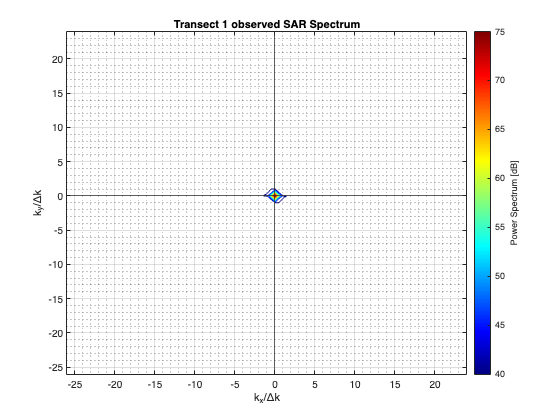

Done


% Spectral bandwidth calculation
func = helperFunctions;
if multipleWaveSpectra
    S_1 = S(:,:,5);
else
    S_1 = S;
end
S_1 = S_1(2:end);
S_1 = func.resize(S_1(2:end),w);
for i=2:length(w)
    dw(i) = w(i)-w(i-1);
end
dw = mean(dw);
S_norm = S_1 / (trapz(S_1).*dw);
spectralMean = trapz(w.*S_norm).*dw;
spectralVar = trapz((w-spectralMean).^2.*S_norm).*dw;
spectralBW = sqrt(spectralVar);
plotTransectSARSpectrum = true;
transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

spectrumThreshold =57; 
%57 has been good previously
if plotTransectSARSpectrum
    disp('Generating plot...');
    for i = 1:length(transectsToPlot)
        transectNum = transectsToPlot(i);
        intensityFFT = abs(fftshift(fft2(transectData(:,:,transectNum))));
        SARSpectrumPlot(intensityFFT,spectrumThreshold,spectralBW,1);
        title(['Transect ', num2str(transectNum),' observed SAR Spectrum'])
        %matlab2tikz(['../plots/results/observedSARSpectrum_',num2str(i),'.tex'])
    end
    disp('Done');
end    

## Hasselmann Procedure

The generated SAR spectrum, as derived by Hasselmann and Hasselmann, generates a SAR spectrum of the generated wave spectrum.

nonLinOrder = 1;
incidenceAngle = incidenceAngle(:,:,1);
r = ones(size(incidenceAngle));
intensityFFT = abs(fftshift(fft2(transectData(:,:,1))));
P_s_pipeline = generateSARSpectrumOceanWaves(k,k_y,k_x,E_k,metadata,incidenceAngle,r,nonLinOrder,w);
plotGeneratedSARSpectrum = true;
if plotGeneratedSARSpectrum
    spectrumThresholdGen = 0;
    SARSpectrumPlot(20*log10(abs(P_s_pipeline)),spectrumThresholdGen,spectralBW,0);
    title('Generated SAR Spectrum')
    disp('Done');
    %matlab2tikz(['../plots/generatedSARSpectrum_Verify.tex'])
end 

## Iterate the inversion procedure

Define the number of iterations to minimise the cost function for before clicking "Run".

nonLinOrder = 1;
incidenceAngle = incidenceAngle(:,:,1);
r = ones(size(incidenceAngle));
P_s_lin = imageVarianceSpectrum(k,k_x,k_y,k_inv,k_x_inv,k_y_inv,E_k,E_k_inv,metadata,incidenceAngle);
E_k_inv = func.resize(E_k_inv(:,1:end-7),E_k);
[p_s_coeff,beta,xi_sqr,~] = quasilinearCoeff(k,k_y,k_x,E_k,metadata,incidenceAngle);
p_s_coeff_inv = quasilinearCoeff(k_inv,k_y_inv,k_x_inv,E_k_inv,metadata,incidenceAngle);
mu = calculateWeight(intensityFFT);
B = calculateNormalisationConstant(E_k);

E_k = func.resize(E_k(2:end,2:end),incidenceAngle);
E_k_inv = func.resize(E_k_inv(2:end,2:end),incidenceAngle);

look = func.getLook(metadata);
look = func.look(look);
polarisation = func.getPolarisation(metadata);
%k_y = func.resize(k_y,th(1,:));
k_l = func.kl(look,k_y);
k_l_inv = func.kl(look,k_y_inv);
omega = func.omega(k);
mu_Th = 0.5;
Th_k = func.hydroMTF(omega,mu_Th,k,k_y);
Th_k = func.resize(Th_k(2:end),omega);
Tt_k = func.tiltMTF(polarisation,k_l,incidenceAngle);
TR_k = func.rarMTF(Tt_k,Th_k);

Th_k_inv = func.hydroMTF(omega,mu_Th,k_inv,k_y_inv);
Th_k = func.resize(Th_k_inv(2:end),omega);
Tt_k_inv = func.tiltMTF(polarisation,k_l_inv,incidenceAngle);
TR_k_inv = func.rarMTF(Tt_k_inv,Th_k_inv);
TR_k_inv = func.resize(TR_k_inv(:,1:end-1),E_k);

Tv_k = func.rangeVelocityTF(omega,incidenceAngle,k_l,k);
Tv_k = func.resize(Tv_k(:,2:end),E_k);

Tvb_k = func.velocityBunchingMTF(beta,k_x,Tv_k);
Tvb_k = func.resize(Tvb_k(:,2:end),E_k);

Tv_k_inv = func.rangeVelocityTF(omega,incidenceAngle,k_l,fliplr(-k));
Tv_k_inv = func.resize(Tv_k_inv(:,2:end-3),E_k);

Tvb_k_inv = func.velocityBunchingMTF(beta,k_x_inv,Tv_k_inv);
Tvb_k_inv = func.resize(Tvb_k_inv(:,2:end-5),E_k);

Ts_k_inv = func.sarImagingMTF(TR_k_inv,Tvb_k_inv);
Ts_k = func.sarImagingMTF(TR_k,Tvb_k);

[M, N] = size(intensityFFT);
dx = spectralBW;
dy = spectralBW;
kx = (-M/2:M/2-1) / (M * dx);
ky = (-N/2:N/2-1) / (N * dy);
% Calculate Δk (the spacing between k values)
dk_x = kx(2) - kx(1);
dk_y = ky(2) - ky(1);
P_s_pipeline = generateSARSpectrumOceanWaves(k,k_y,k_x,E_k,metadata,incidenceAngle,r,nonLinOrder,w);

m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 


iterations = 5;
iterationVec = linspace(1,iterations,iterations);
[J,En,Pn,~, ~, sigWaveHeight,sigWavePeriod] = inversion(iterations,P_s_pipeline,intensityFFT,E_k,E_k_inv,k,k_x,k_y,B,mu,Ts_k,Ts_k_inv,P_s_lin,p_s_coeff,p_s_coeff_inv,dk_x,dk_y,metadata,incidenceAngle,r,w,D,theta,d);

m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 2.2924 with iterations = 1
Significant Wave Period = 11.033 with iterations = 1
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 2.2947 with iterations = 2
Significant Wave Period = 11.033 with iterations = 2
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 2.2947 with iterations = 3
Significant Wave Period = 11.033 with iterations = 3
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 2.2947 with iterations = 4
Significant Wave Period = 11.033 with iterations = 4
m = 0, n = 1 
P_(n,2n-2) used
m = 1, n = 1 
P_(n,2n-1) used 
m = 2, n = 1 
P_(n,2n) used 
Significant Wave Height = 2.2947 with iterations = 5
Significant Wave Period = 11.033 with iterations = 5


[En_w, En_w_th] = waveNumberConvert(En,k,w,theta,D,d);
 

## Best-fit Data Plots

All output best-fit plots can be toggled and displayed.

### Significant Wave Height

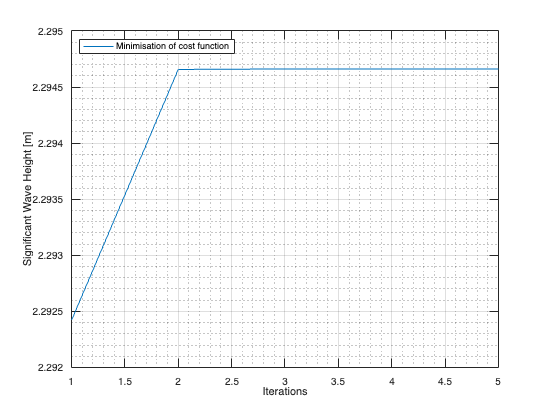

% Plot waveHeight
plotBFHeight = true;
if plotBFHeight
    figure;
    plot(iterationVec,sigWaveHeight, 'DisplayName','Minimisation of cost function');
    %yline(waveVals.significantWaveHeight,'LineStyle','--','Color',	'r','DisplayName','First-guess wave spectrum');
    ylabel('Significant Wave Height [m]')
    xlabel('Iterations')
    grid on;
    grid minor;
    legend('show','Location','northwest')
    %matlab2tikz(['../plots/results/15Oct/sigWaveHeightMinimisation2_5iterations_15Oct.tex']);
end

### Significant Wave Period

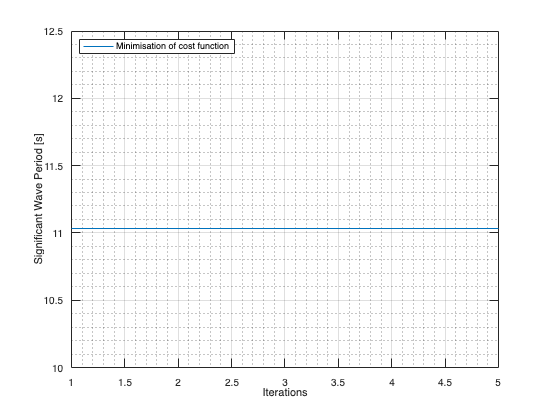

plotBFPeriod = true;
if plotBFPeriod
    figure;
    plot(iterationVec,sigWavePeriod, 'DisplayName','Minimisation of cost function');
    %yline(waveVals2.significantWavePeriod,'LineStyle','--','Color',	'r','DisplayName','First-guess wave spectrum');
    ylabel('Significant Wave Period [s]')
    xlabel('Iterations')
    grid on;
    grid minor;
    legend('show','Location','northwest')
    %matlab2tikz(['../plots/results/15Oct/sigWavePeriodMinimisation2_5iterations_15Oct.tex']);
end

### Two-dimensional wave spectra

plotMinimised2DWaveSpectrum = true;
if plotMinimised2DWaveSpectrum
    wOrK = 1;
    contourOrSurf =1;
    if wOrK
        disp('Generating plot...');
        twoDWaveSpectrumPlot(En,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    else
        disp('Generating plot...');
        twoDWaveSpectrumPlot(En_w_th,wOrK,contourOrSurf,w,theta,k_x,k_y); 
        disp('Done');
    end    
end 

### Best-fit SAR Spectrum

plotMinimisedSARSpectrum = true;
if plotMinimisedSARSpectrum
    spectrumThresholdMin = 130;
    disp('Generating plot...')
    SARSpectrumPlot(20*log10(abs(Pn)),spectrumThresholdMin,spectralBW);
    title('Best-fit SAR Spectrum')
    disp('Done');
end  

### One-dimensional Wave Specturm

plotEnw = true;
if plotEnw
    figure;
    plot(w,En_w);
    grid on;
    xlabel('\omega [rad/s]')
    ylabel('E(\omega) [m^2/rad/Hz]')
    grid minor;
    set(gca,'XTick',0:pi/2:2*pi) 
    set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
    set(gca,'FontSize',12)
end

### Comparison between Best-fit and First-guess Wave Spectra

plotBFandFGWave = false;
BFandFGwPeak = false;
if plotBFandFGWave
    figure;
    plot(w,En_w,'DisplayName','Best-fit spectrum');
    hold on;
    plot(w,S,'DisplayName','First-guess spectrum');
    maxIndexS = find(S == max(S));
    maxIndexEn = find(En_w == max(En_w));
    title(['One-dimensional wave spectrum, E(\omega) at ', num2str(waveVals.latitude(1,1)), 'S, ', num2str(waveVals.longitude(1,1)), 'E'])
    xlabel('\omega [rad/s]')
    ylabel('E(\omega) [m^2/rad/Hz]')
    grid on;
    if BFandFGwPeak
        xline(w(maxIndexS),LineWidth=1,DisplayName=['\omega = ',num2str(round(w(maxIndexS),3))],Color="#D95319",LineStyle="--");
        xline(w(maxIndexEn),LineWidth=1,DisplayName=['\omega = ',num2str(round(w(maxIndexEn),3))],Color="#0072BD",LineStyle="--");
    end
    hold off;
    legend('show');
    xlabel('\omega [rad/s]')
    ylabel('E(\omega) [m^2/rad/Hz]')
    grid on;
    grid minor;
    set(gca,'XTick',0:pi/2:2*pi) 
    set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
    set(gca,'FontSize',12)
    %matlab2tikz(['../plots/results/15Oct/oneDWaveSpec2_5iterations_15Oct.tex']);
end

### Cost Function, J

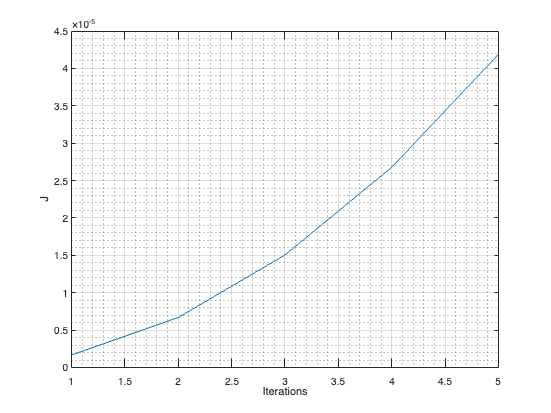

plotJ = true;
if plotJ
    figure;
    plot(iterationVec,J)
    xlabel('Iterations')
    ylabel('J')
    grid on;
    grid minor;
    %matlab2tikz(['../plots/results/15Oct/J2_5iterations_15Oct.tex']);
end

## Output Parameters

The best-fit significant wave height and period can be saved as .csv files. These variables are also available in the Workspace.

saveWaveParams = false;
writematrix(sigWaveHeight,'SignificantWaveHeight.csv');
writematrix(sigWavePeriod,'SignificantWavePeriod.csv');

If the pipeline has not been run yet, click "Run".